# Scientific Programming, Worksheet 4, Ex. 8

*Written by: Kundyz Muktar, Course: Scientific Programming (2025), MATLAB version: R2023a*

clear; clc; close all;

## Part A

disp('===== (a) Polynomial Test =====');

===== (a) Polynomial Test =====


z = [0.5 4.2 0.7;
     0.5 0.7 4.2];  % 2x3 matrix
k = 2;
q_exact_a = 27.0383749999;  

f1 = @(x,y) x.^k;
f2 = @(x,y) y.^k;

% Quadrature order
nx = 5;  
ny = 5;  % same in both dires


all_perms = perms([1 2 3]);  % permutations of [1,2,3]
for p = 1:size(all_perms,1)
    
    curr_perm = all_perms(p,:);
    z_permed = z(:, curr_perm);

    Qx = DuffyQuadratureTriangle(z_permed, f1, nx, ny);
    Qy = DuffyQuadratureTriangle(z_permed, f2, nx, ny);

    fprintf('Permutation %s => Qx=%.6f, Qy=%.6f\n', ...
        mat2str(curr_perm), Qx, Qy);
end

z =     0.5000    4.2000    0.7000
    0.5000    0.7000    4.2000


permIndices =      3     2     1


zPerm =     0.7000    4.2000    0.5000
    4.2000    0.7000    0.5000


Permutation [3 2 1] => Qx=47.100083, Qy=27.591958


z =     0.5000    4.2000    0.7000
    0.5000    0.7000    4.2000


permIndices =      3     1     2


zPerm =     0.7000    0.5000    4.2000
    4.2000    0.5000    0.7000


Permutation [3 1 2] => Qx=12.167458, Qy=26.499958


z =     0.5000    4.2000    0.7000
    0.5000    0.7000    4.2000


permIndices =      2     3     1


zPerm =     4.2000    0.7000    0.5000
    0.7000    4.2000    0.5000


Permutation [2 3 1] => Qx=27.591958, Qy=47.100083


z =     0.5000    4.2000    0.7000
    0.5000    0.7000    4.2000


permIndices =      2     1     3


zPerm =     4.2000    0.5000    0.7000
    0.7000    0.5000    4.2000


Permutation [2 1 3] => Qx=26.499958, Qy=12.167458


z =     0.5000    4.2000    0.7000
    0.5000    0.7000    4.2000


permIndices =      1     3     2


zPerm =     0.5000    0.7000    4.2000
    0.5000    4.2000    0.7000


Permutation [1 3 2] => Qx=12.440458, Qy=46.281083


z =     0.5000    4.2000    0.7000
    0.5000    0.7000    4.2000


permIndices =      1     2     3


zPerm =     0.5000    4.2000    0.7000
    0.5000    0.7000    4.2000


Permutation [1 2 3] => Qx=46.281083, Qy=12.440458



% Compare one of them to q_exact_a for a sense of error
q_approx = DuffyQuadratureTriangle(z, f1, nx, ny);
err_a = abs(q_approx - q_exact_a);

fprintf('\nFor f1(x,y)=x^k with k=%d and the original z,\n', k);


For f1(x,y)=x^k with k=2 and the original z,


fprintf(' Qapprox = %.8f, Qref = %.8f, Error=%.2e\n\n', q_approx, q_exact_a, err_a);

 Qapprox = 46.28108333, Qref = 27.03837500, Error=1.92e+01



## Part B

disp('===== (b) Sin(2π(x+y)) Test =====');

===== (b) Sin(2π(x+y)) Test =====


f_b = @(x,y) sin(2*pi*(x + y));
q_exact_b = -0.46041808541078;  % given reference value

n_values = 1:8;
err_b = zeros(size(n_values));

for idx = 1:length(n_values)
    n = n_values(idx);
    q_approx_b = DuffyQuadratureTriangle(z, f_b, n, n);
    err_b(idx) = abs(q_approx_b - q_exact_b);
end

% Print results in a small table
disp('   n      Qapprox        Error');

   n      Qapprox        Error


for idx = 1:length(n_values)
    fprintf('%4d   % .8f   % .2e\n', ...
        n_values(idx), ...
        DuffyQuadratureTriangle(z, f_b, n_values(idx), n_values(idx)), ...
        err_b(idx));
end

   1   -0.00000000    4.60e-01
   2   -2.00581717    1.55e+00
   3   -2.74872390    2.29e+00
   4    1.65166989    2.11e+00
   5   -0.28586430    1.75e-01
   6    0.38762314    8.48e-01
   7    1.46581390    1.93e+00
   8   -0.26806928    1.92e-01


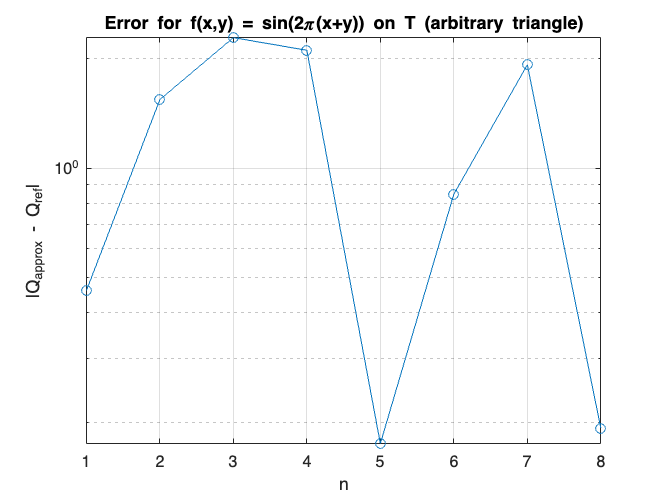


% Plot error on semilog scale
figure;
semilogy(n_values, err_b, 'o-');
grid on;
xlabel('n');
ylabel('|Q_{approx} - Q_{ref}|');
title('Error for f(x,y) = sin(2\pi(x+y)) on T (arbitrary triangle)');

f_tref = f(Ψ), where **Ψ **is the affine transformation from **ref triangle** to an **arbitrary triangle**. 

function Q = DuffyQuadratureTriangle(z, f, nx, ny)


    % extract the vertices
    z1 = z(:,1);
    z2 = z(:,2);
    z3 = z(:,3);

    f_tref = @(xi, eta) f( z1(1) + xi*(z2(1)-z1(1)) + eta*(z3(1)-z1(1)), ...
                            z1(2) + xi*(z2(2)-z1(2)) + eta*(z3(2)-z1(2)) );


    Q_ref = DuffyQuadratureTref(0, 1, 0, 1, f_tref, nx, ny);
    T = abs( det( [
    1      1      1;
    z(1,1) z(1,2) z(1,3);
    z(2,1) z(2,2) z(2,3)] ) ); %scaling factor

    Q = T * Q_ref;
end


*Taken from Worksheet 4, Ex 5:*

function Q = DuffyQuadratureTref(a, b, c, d, f, nx, ny)

    [x, wX] = quadrature(a, b, nx); % x direction
    [y, wY] = quadrature(c, d, ny); % y direction
 
    Q = 0;
    for i = 1:nx
        for j = 1:ny
            Q = Q + wX(i) * wY(j) * (1-x(j)) *   f(  x(i), (1-x(i))*x(j)   );
        end
    end
end


*Taken from Worksheet 3, Ex 3:*

function [x, w] = quadrature(a, b, n)
    if n == 1
        x = a;  % if only one node, choose the left endpoint (could also choose the midpoint)
        w = (b-a);
        return
    end

    h = (b - a) / (n - 1);  % quadrature step size
    x = a:h:b;
    

    x01 = linspace(0, 1, n); 
    w01 = quadratureWeights(x01);
    w = (b - a) * w01;
end

%% from ex 1 or 2
function w = quadratureWeights(x)
    n = numel(x);
    A = zeros(n,n);
    b = zeros(n,1);

    for row = 0:n-1
        A(row+1,:) = x.^row;
        b(row+1)   = 1/(row+1);
    end

    w = A\b;
end
%% from ex 1
function [A, b_vals] = build_A_b(k, N, x_vals)
    % Here k is the maximum polynomial degree (so there are k+1 moments)
    A = zeros(k+1, N);
    b_vals = zeros(k+1, 1);
    for row = 0:k
        A(row+1, :) = x_vals.^row;
        b_vals(row+1) = 1/(row+1);
    end
end


